clc;
close all;
clear;
format long;
B = 0.8e9; %带宽
f0 = 9.6e9;
fs= 40e9;  %采样频率 
Ts=1/fs; %
T = 20e-6;   %调制时间50us
num = round(T / Ts); %周期采样点数
k = B / T;  %斜率
t = 0 : 1/fs : (num-1)/fs;

window = 1024;
overLap = 512;
nfft = 5000;
num1=19;
B1=B/num1;
T1=T/num1;
t1= 0 : 1/fs : (num-1)/fs/num1;


## M1=[0  1  2  3  4  5  6  7  8  9  10  11  12  13  14  15  16  17  18]

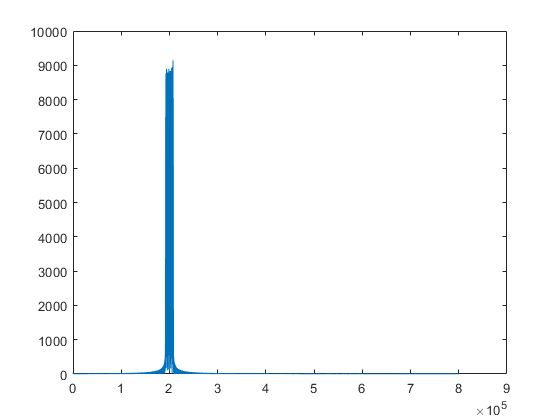

M1=[0  1  2  3  4  5  6  7  8  9  10  11  12  13  14  15  16  17  18];
lfm_1=[];
for i=1:num1
    y_c1=exp(1j *2 * pi * ((f0 + B1 * M1(i)) * t1 + 0.5 * k * t1.^2));
    y_c0=exp(1j *2 * pi * ((f0 + B1 * (M1(i)+1)) * t1 - 0.5 * k * t1.^2));
    if(mod(i,2) == 0)
        lfm_1=[lfm_1,y_c1];
    else
        lfm_1=[lfm_1,y_c0];
    end
end
plot(abs(fft(lfm_1)))

## M2=[0  2  4  6  8  10  12  14  16  18  1  3  5  7  9  11  13  15  17]

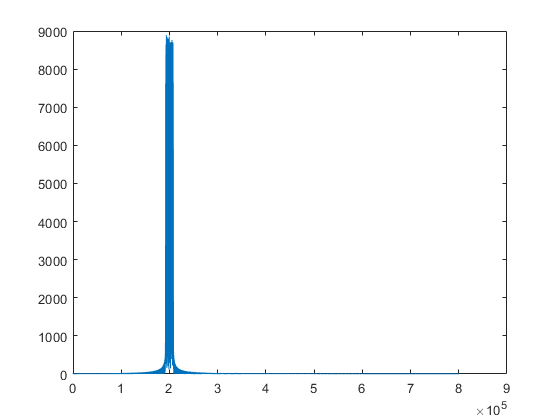

M2=[0  2  4  6  8  10  12  14  16  18  1  3  5  7  9  11  13  15  17];
lfm_2=[];
for i=1:num1
    y_c1=exp(1j *2 * pi * ((f0 + B1 * M2(i)) * t1 + 0.5 * k * t1.^2));
    y_c0=exp(1j *2 * pi * ((f0 + B1 * (M2(i)+1)) * t1 - 0.5 * k * t1.^2));
    if(mod(i,2) == 0)
        lfm_2=[lfm_2,y_c1];
    else
        lfm_2=[lfm_2,y_c0];
    end
end
plot(abs(fft(lfm_2)))

## M3=[0  3  6  9  12  15  18  2  5  8  11  14  17  1  4  7  10  13  16]

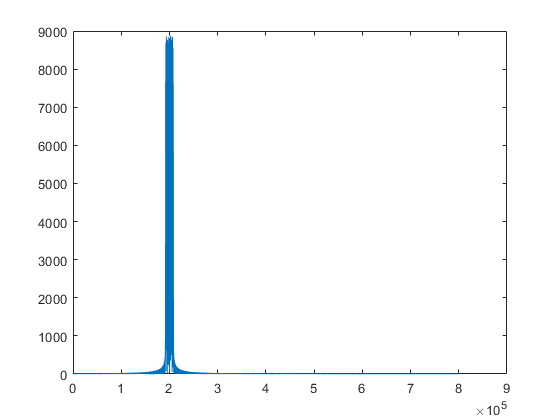

M3=[0  3  6  9  12  15  18  2  5  8  11  14  17  1  4  7  10  13  16];
lfm_3=[];
for i=1:num1
    y_c1=exp(1j *2 * pi * ((f0 + B1 * M3(i)) * t1 + 0.5 * k * t1.^2));
    y_c0=exp(1j *2 * pi * ((f0 + B1 * (M3(i)+1)) * t1 - 0.5 * k * t1.^2));
    if(mod(i,2) == 0)
        lfm_3=[lfm_3,y_c1];
    else
        lfm_3=[lfm_3,y_c0];
    end
end
plot(abs(fft(lfm_3)))

## M4=[0  4  8  12  16  1  5  9  13  17  2  6  10  14  18  3  7  11  15]

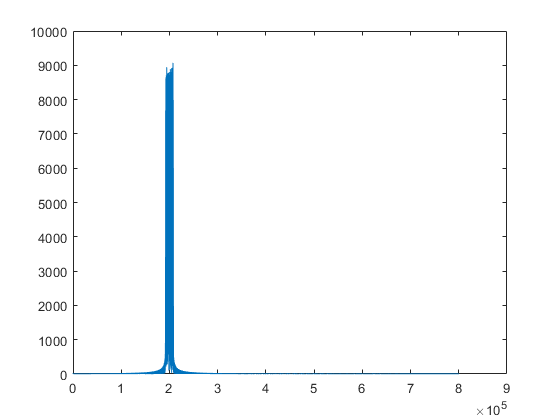

M4=[0  4  8  12  16  1  5  9  13  17  2  6  10  14  18  3  7  11  15];
lfm_4=[];
for i=1:num1
    y_c1=exp(1j *2 * pi * ((f0 + B1 * M4(i)) * t1 + 0.5 * k * t1.^2));
    y_c0=exp(1j *2 * pi * ((f0 + B1 * (M4(i)+1)) * t1 - 0.5 * k * t1.^2));
    if(mod(i,2) == 0)
        lfm_4=[lfm_4,y_c1];
    else
        lfm_4=[lfm_4,y_c0];
    end
end
plot(abs(fft(lfm_4)))

## M5=[0  5  10  15  1  6  11  16  2  7  12  17  3  8  13  18  4  9  14]

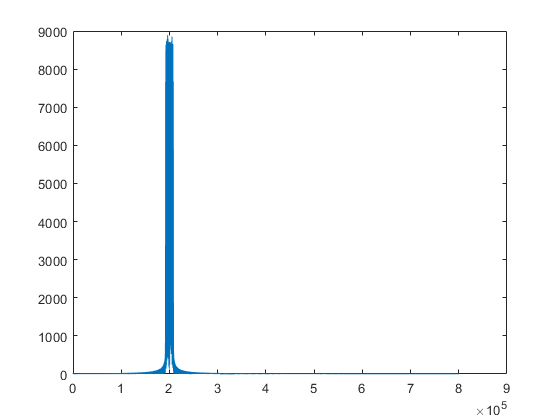

M5=[0  5  10  15  1  6  11  16  2  7  12  17  3  8  13  18  4  9  14];
lfm_5=[];
for i=1:num1
    y_c1=exp(1j *2 * pi * ((f0 + B1 * M5(i)) * t1 + 0.5 * k * t1.^2));
    y_c0=exp(1j *2 * pi * ((f0 + B1 * (M5(i)+1)) * t1 - 0.5 * k * t1.^2));
    if(mod(i,2) == 0)
        lfm_5=[lfm_5,y_c1];
    else
        lfm_5=[lfm_5,y_c0];
    end
end
plot(abs(fft(lfm_5)))

## M6=[0  6  12  18  5  11  17  4  10  16  3  9  15  2  8  14  1  7  13]

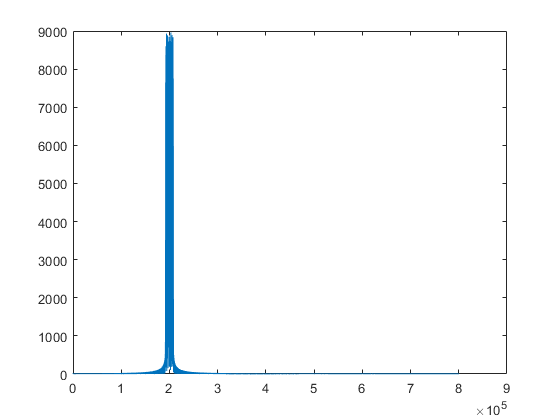

M6=[0  6  12  18  5  11  17  4  10  16  3  9  15  2  8  14  1  7  13];
lfm_6=[];
for i=1:num1
    y_c1=exp(1j *2 * pi * ((f0 + B1 * M6(i)) * t1 + 0.5 * k * t1.^2));
    y_c0=exp(1j *2 * pi * ((f0 + B1 * (M6(i)+1)) * t1 - 0.5 * k * t1.^2));
    if(mod(i,2) == 0)
        lfm_6=[lfm_6,y_c1];
    else
        lfm_6=[lfm_6,y_c0];
    end
end
plot(abs(fft(lfm_6)))

## M7=[0  7  14  2  9  16  4  11  18  6  13  1  8  15  3  10  17  5  12]

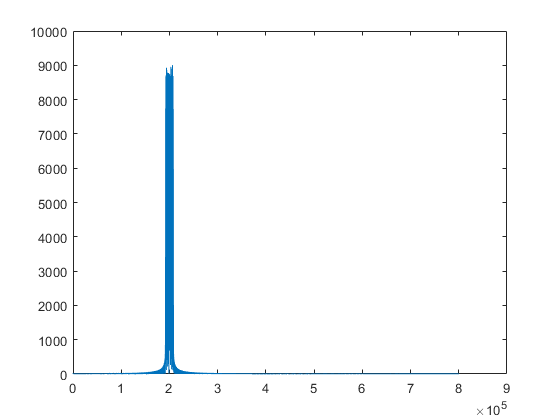

M7=[0  7  14  2  9  16  4  11  18  6  13  1  8  15  3  10  17  5  12];
lfm_7=[];
for i=1:num1
    y_c1=exp(1j *2 * pi * ((f0 + B1 * M7(i)) * t1 + 0.5 * k * t1.^2));
    y_c0=exp(1j *2 * pi * ((f0 + B1 * (M7(i)+1)) * t1 - 0.5 * k * t1.^2));
    if(mod(i,2) == 0)
        lfm_7=[lfm_7,y_c1];
    else
        lfm_7=[lfm_7,y_c0];
    end
end
plot(abs(fft(lfm_7)))

## M8=[0  8  16  5  13  2  10  18  7  15  4  12  1  9  17  6  14  3  11]

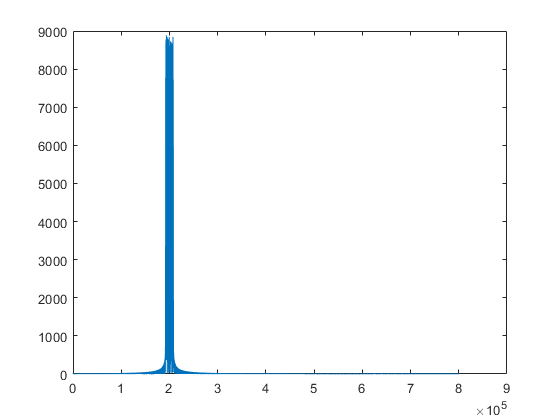

M8=[0  8  16  5  13  2  10  18  7  15  4  12  1  9  17  6  14  3  11];
lfm_8=[];
for i=1:num1
    y_c1=exp(1j *2 * pi * ((f0 + B1 * M8(i)) * t1 + 0.5 * k * t1.^2));
    y_c0=exp(1j *2 * pi * ((f0 + B1 * (M8(i)+1)) * t1 - 0.5 * k * t1.^2));
    if(mod(i,2) == 0)
        lfm_8=[lfm_8,y_c1];
    else
        lfm_8=[lfm_8,y_c0];
    end
end
plot(abs(fft(lfm_8)))

## 信号处理

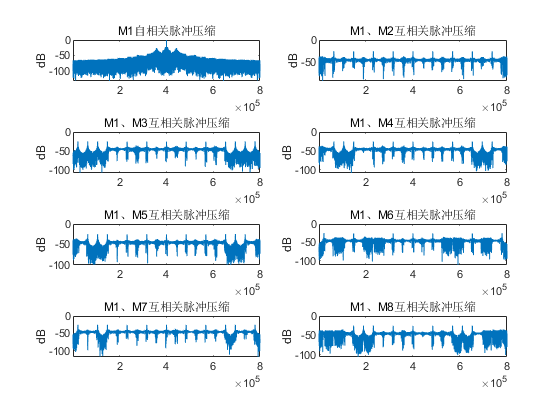

wn=0.54-0.46*cos(2*pi*t./T);
hn=0.9-0.1*cos(2*pi*t./T);
sjc=1-abs(1-2*t./T);
sinch=sin(pi*t./T);
ksc = kaiser(num,6);
wn=ifft(fft(wn,800014));
figure(1)
subplot(4,2,1)
Hw=conj(fft((lfm_1)));
Lfm_r=fft(((lfm_1)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
Qm=max(Q);
plot(20*log10(Q/Qm))
title('M1自相关脉冲压缩')
ylabel("dB")
figure(2)
subplot(4,2,1)
Hw=conj(fft((lfm_1)));
Lfm_r=fft(((lfm_1)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
Qm=max(Q);
plot(20*log10(Q/Qm))
title('M1自相关脉冲压缩')
axis([-inf inf -inf 0])
ylabel("dB")
figure(2)
subplot(4,2,2)
Hw=conj(fft((lfm_1)));
Lfm_r=fft(((lfm_2)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
plot(20*log10(Q/Qm))
title('M1、M2互相关脉冲压缩')
axis([-inf inf -inf 0])
ylabel("dB")
figure(2)
subplot(4,2,3)
Hw=conj(fft((lfm_1)));
Lfm_r=fft(((lfm_3)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
plot(20*log10(Q/Qm))
title('M1、M3互相关脉冲压缩')
axis([-inf inf -inf 0])
ylabel("dB")
figure(2)
subplot(4,2,4)
Hw=conj(fft((lfm_1)));
Lfm_r=fft(((lfm_4)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
plot(20*log10(Q/Qm))
title('M1、M4互相关脉冲压缩')
axis([-inf inf -inf 0])
ylabel("dB")
figure(2)
subplot(4,2,5)
Hw=conj(fft((lfm_1)));
Lfm_r=fft(((lfm_5)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
plot(20*log10(Q/Qm))
title('M1、M5互相关脉冲压缩')
axis([-inf inf -inf 0])
ylabel("dB")
figure(2)
subplot(4,2,6)
Hw=conj(fft((lfm_1)));
Lfm_r=fft(((lfm_6)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
plot(20*log10(Q/Qm))
title('M1、M6互相关脉冲压缩')
axis([-inf inf -inf 0])
ylabel("dB")
figure(2)
subplot(4,2,7)
Hw=conj(fft((lfm_1)));
Lfm_r=fft(((lfm_7)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
plot(20*log10(Q/Qm))
title('M1、M7互相关脉冲压缩')
axis([-inf inf -inf 0])
ylabel("dB")
figure(2)
subplot(4,2,8)
Hw=conj(fft((lfm_1)));
Lfm_r=fft(((lfm_8)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
plot(20*log10(Q/Qm))
title('M1、M8互相关脉冲压缩')
axis([-inf inf -inf 0])
ylabel("dB")

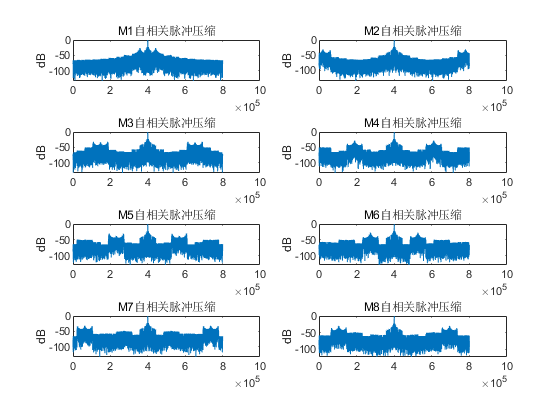


figure(1)
subplot(4,2,2)
Hw=conj(fft((lfm_2)));
Lfm_r=fft(((lfm_2)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
Qm=max(Q);
plot(20*log10(Q/Qm))
title('M2自相关脉冲压缩')
ylabel("dB")

figure(1)
subplot(4,2,3)
Hw=conj(fft((lfm_3)));
Lfm_r=fft(((lfm_3)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
Qm=max(Q);
plot(20*log10(Q/Qm))
title('M3自相关脉冲压缩')
ylabel("dB")

figure(1)
subplot(4,2,4)
Hw=conj(fft((lfm_4)));
Lfm_r=fft(((lfm_4)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
Qm=max(Q);
plot(20*log10(Q/Qm))
title('M4自相关脉冲压缩')
ylabel("dB")

figure(1)
subplot(4,2,5)
Hw=conj(fft((lfm_5)));
Lfm_r=fft(((lfm_5)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
Qm=max(Q);
plot(20*log10(Q/Qm))
title('M5自相关脉冲压缩')
ylabel("dB")

figure(1)
subplot(4,2,6)
Hw=conj(fft((lfm_6)));
Lfm_r=fft(((lfm_6)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
Qm=max(Q);
plot(20*log10(Q/Qm))
title('M6自相关脉冲压缩')
ylabel("dB")

figure(1)
subplot(4,2,7)
Hw=conj(fft((lfm_7)));
Lfm_r=fft(((lfm_7)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
Qm=max(Q);
plot(20*log10(Q/Qm))
title('M7自相关脉冲压缩')
ylabel("dB")

figure(1)
subplot(4,2,8)
Hw=conj(fft((lfm_8)));
Lfm_r=fft(((lfm_8)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
Qm=max(Q);
plot(20*log10(Q/Qm))
title('M8自相关脉冲压缩')
ylabel("dB")